## Time Series and Spectrogram

### Waveform #1

TS_freq1 = 151;  % Frequency in Hz
PulseLength1 = 650;  % Pulse Length in milliseconds
AmplitudedB1 = 0;
StartTime1 = 0;
Amplitude1 = 10.^(AmplitudedB1/20);

### Waveform #2


TS_freq2 = 841;  % Frequency in Hz
PulseLength2 = 280;  % Pulse Length in milliseconds
AmplitudedB2 = 0;
Amplitude2 = 10.^(AmplitudedB2/20);
StartTime2 = 580;

### Display Waveforms

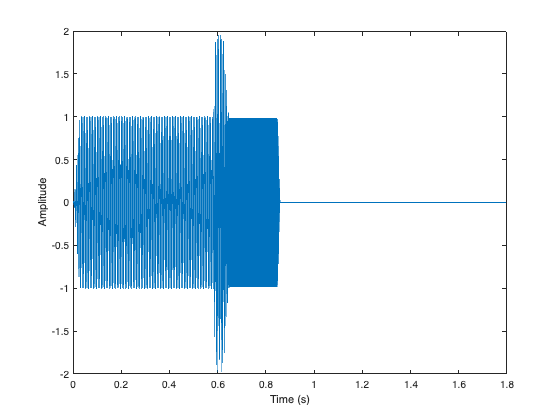

TimeWindow = 1.8;

dt1 = (1/TS_freq1)/10;
dt2 = (1/TS_freq2)/10;
if dt1 < dt2
    t = 0:dt1:TimeWindow;
    dt = dt1;
else
    t = 0:dt2:TimeWindow;
    dt = dt2;
end

ind1 = (t - StartTime1/1000) >= 0 & (t - StartTime1/1000) <= PulseLength1/1000;
ind2 = (t - StartTime2/1000) >= 0 & (t - StartTime2/1000) <= PulseLength2/1000;

WaveFormTmp1 = Amplitude1*sin(2*pi*TS_freq1*(t(ind1) - StartTime1/1000)).*tukeywin(length(find(ind1)),0.1).';
WaveFormTmp2 = Amplitude2*sin(2*pi*TS_freq2*(t(ind2) - StartTime2/1000)).*tukeywin(length(find(ind2)),0.1).';
WaveForm1 = 0.*t;
WaveForm2 = 0.*t;
WaveForm1(ind1) = WaveFormTmp1;
WaveForm2(ind2) = WaveFormTmp2;

plot(t,WaveForm1+WaveForm2)
a = gca;
a.XLabel.String = 'Time (s)';
a.YLabel.String = 'Amplitude';
a.YLim = [-2 2];

### Display Spectrogram

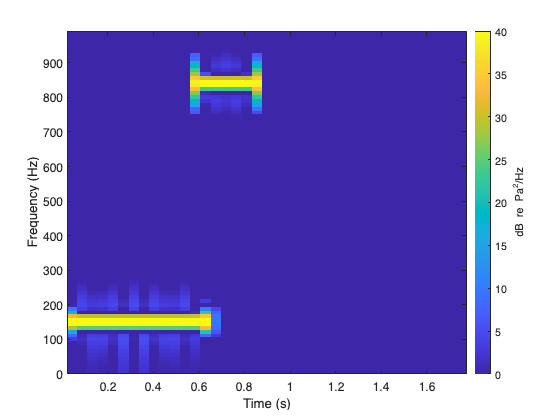

Nt = length(t);
Nham = floor(Nt/20);
[S,F,T] = spectrogram(WaveForm1+WaveForm2,Nham,floor(Nham/2),Nham,1/dt) ;
imagesc(T,F,20*log10(abs(S)),[0 40])
cb = colorbar;
cb.Label.String = 'dB re Pa^2/Hz';
a = gca;
a.XLabel.String = 'Time (s)';
a.YLabel.String = 'Frequency (Hz)';
a.YLim = [0 TS_freq2 + TS_freq1];
a.FontSize = 12;
axis xy

### Linear Frequency Modulated (LFM) pulse

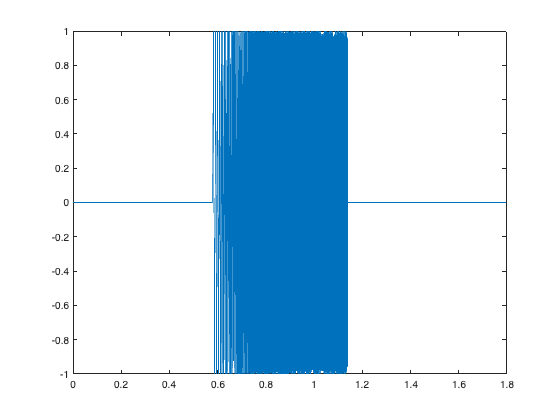

F0 = 100;
F1 = 810;
LFMLength = 560;  % Pulse Length in milliseconds
AmplitudedBLFM = 0;
AmplitudeLFM = 10.^(AmplitudedB2/20);
StartTime2 = 580;
dtLFM = (1/F1)/10;
TimeWindowLFM = 1.8;
LFMTime = 0:dtLFM:(LFMLength/1000);

LFMSignal = sin(2*pi*(F0 + (F1 - F0)*LFMTime/(2*LFMLength/1000)).*LFMTime);
Time3 = 0:dtLFM:(TimeWindowLFM);
Waveform3 = 0.*Time3;
Waveform3(round(StartTime2/(1000*dtLFM)) + (0:length(LFMTime)-1)) = LFMSignal;

plot(Time3,Waveform3)

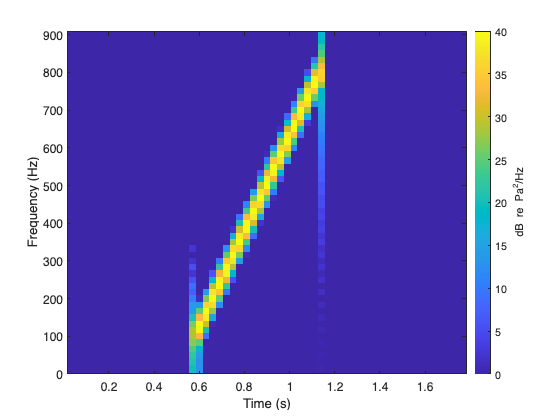

Nt3 = length(Time3);
Nham3 = floor(Nt3/30);
[S_lfm,F_lfm,T_lfm] = spectrogram(Waveform3,Nham3,floor(Nham3/2),Nham3,1/dtLFM) ;
imagesc(T_lfm,F_lfm,20*log10(abs(S_lfm)),[0 40])
cb = colorbar;
cb.Label.String = 'dB re Pa^2/Hz';
a = gca;
a.XLabel.String = 'Time (s)';
a.YLabel.String = 'Frequency (Hz)';
a.YLim = [0 F0+F1];
a.FontSize = 12;
axis xy

## Circular Piston Transducer

This example shows the beam pattern for a baffled circle piston, an approximation to the a circular piston transducer.

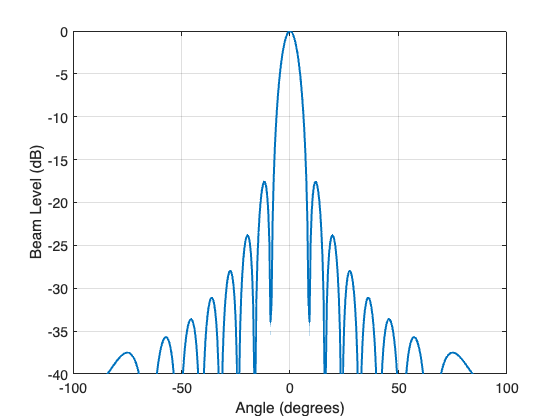

f = 20;      % Frequency in kHz
rho0 = 1;
c = 1500;
a = 0.3;
r = 10;

omega = 2*pi*f*1000;
k = omega/c;

theta = -90:0.5:90;
u = k*a*sin(theta*pi/180);

projInt = abs((rho0*c*k*a*a/(2*r)).*...
    (2*besselj(1,u)./u)).^2;
ind = find(theta == 0);
axisInt = abs(rho0*c*k*a*a/(2*r)).^2;
projInt(ind) = axisInt;

plotType = 0;
plotScale = "Decibels";

if plotType == 0

    if plotScale == 'Decibels'

        plot(theta,10*log10(projInt/axisInt),'linewidth',2)
        a1 = gca;
        a1.YLim = [-40 0];
        a1.FontSize = 14;
        a1.XLabel.String = 'Angle (degrees)';
        a1.YLabel.String = 'Beam Level (dB)';
        grid on

    else

        plot(theta,projInt/axisInt,'linewidth',2)
        a1 = gca;
        a1.YLim = 10.^([-40 0]/10);
        a1.FontSize = 14;
        a1.XLabel.String = 'Angle (degrees)';
        a1.YLabel.String = 'Beam Level';

    end


elseif plotType == 1

    if plotScale == 'Decibels'

        polarplot(theta*pi/180,10*log10(projInt/axisInt),'linewidth',2)
        a1 = gca;
        a1.RLim = [-40 0];
        a1.ThetaZeroLocation = 'top';
        a1.ThetaLim = [-90 90];
        a1.Title.String = 'Beam Pattern (dB)';
        a1.FontSize = 14;

    else

        polarplot(theta*pi/180,projInt/axisInt,'linewidth',2)
        a1 = gca;
        a1.RLim = 10.^([-40 0]/10);
        a1.ThetaZeroLocation = 'top';
        a1.ThetaLim = [-90 90];
        a1.Title.String = 'Beam Pattern (Linear Scale)';
        a1.FontSize = 14;

    end

end

ind3dB = find(10*log10(projInt/axisInt) >= -3);
ind6dB = find(10*log10(projInt/axisInt) >= -6);
ind10dB = find(10*log10(projInt/axisInt) >= -10);

bw3dB = abs(theta(ind3dB(1)));
bw6dB = abs(theta(ind6dB(1)));
bw10dB = abs(theta(ind10dB(1)));

bwLabels = {'down 3dB';'down 6 dB';'down 10 dB'};
bwValues = [bw3dB; bw6dB; bw10dB];
varNames = {'Beam Width (degrees)';' '};

T = table(bwValues,bwLabels,'VariableNames',varNames);
display(T)

T = 3×2 table
    Beam Width (degrees)                  
    ____________________    ______________

            3.5             {'down 3dB'  }
              5             {'down 6 dB' }
              6             {'down 10 dB'}


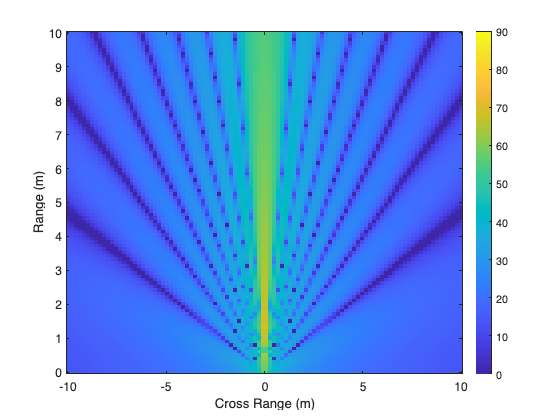

x = linspace(-r,r,100);
y = linspace(0,r,100);

[X,Y] = meshgrid(x,y);

thetaXY = atan2(X,Y);
rXY = sqrt(X.^2 + Y.^2);
u1 = k.*a.*sin(thetaXY);
projIntXY = abs((rho0*c*k*a*a./(2*rXY)).*...
    (2*besselj(1,u1)./u1)).^2;

if plotScale == 'Decibels'
    imagesc(x,y,10*log10(projIntXY))
    a2 = gca;
    a2.YDir = 'normal';
    colorbar
    a2.FontSize = 12;
    a2.CLim = [0 90];
    a2.XLabel.String = 'Cross Range (m)';
    a2.YLabel.String = 'Range (m)';
else
   imagesc(x,y,projIntXY)
    a2 = gca;
    a2.YDir = 'normal';
    colorbar
    a2.FontSize = 12;
    a2.CLim = 10.^([0 60]/10); 
    a2.XLabel.String = 'Cross Range (m)';
    a2.YLabel.String = 'Range (m)';
end